# AMINATA DANIOKO

# Question 3 Part 1


%  SVM Classification 2D examples
%  with different kernels (including wavelets) and different penalization settings
%
%  05/05/03 AR



%% From the this file it displays a distance matric that has different columns of the number of support and number of number saturated on the given data.
%% In the column titled Delta cost is the value in the row has a negative number it is listed as a bad mouve.
%% The figure that appears is a 2D contour map that is shaded flat and used the Gaussian function as the kernel type and the results printed the outputs below.


clear all
close all
clc


n = 1000

n = 1000

sigma=0.3

sigma = 0.3000



[Xapp,yapp,xtest,ytest]=datasets('gaussian',n,0,sigma)

Xapp =     0.1639    0.3270
    0.3271    0.3600
    0.5886    0.7329
    0.3893   -0.2379
    0.2962    0.5583
    0.3401    0.5826
    0.5307    0.1147
    0.3387    1.0836
    0.3328    0.2293
    0.9418    0.6460


yapp =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1



xtest =

  0×2 empty double matrix




ytest =

  0×1 empty double column vector



Xapp=single(Xapp)

Xapp =     0.1639    0.3270
    0.3271    0.3600
    0.5886    0.7329
    0.3893   -0.2379
    0.2962    0.5583
    0.3401    0.5826
    0.5307    0.1147
    0.3387    1.0836
    0.3328    0.2293
    0.9418    0.6460


[Xapp]=normalizemeanstd(Xapp)

Xapp =     0.3833    0.5661
    0.7601    0.6237
    1.3637    1.2747
    0.9035   -0.4199
    0.6886    0.9698
    0.7901    1.0122
    1.2301    0.1955
    0.7868    1.8868
    0.7733    0.3956
    2.1790    1.1230




 
lambda = 1e-7

lambda = 1.0000e-07

C = 10

C = 10



%
%  assymetric C
%

%C=[100*ones(n/2,1); 100*ones(n/2,1)];


% The kernel type used for this figure is the Gaussian 
 kernel='gaussian'

kernel = gaussian

 kerneloption=1 % The parameters is set to equal 1 

kerneloption = 1

 

%  uncomment this is you want to use a wavelet kernel.
%  but you need to install the wavelab toolbox of Donoho et al.
%
% kernel='tensorwavkernel';
% kerneloption.wname='Haar';
% kerneloption.pow=8;
% kerneloption.par=4;
% kerneloption.jmax=5;
% kerneloption.jmin=0;
% kerneloption.crossterm='off';
% kerneloption.coeffj=1/sqrt(2); 
% 
% x=linspace(0,1,20)';
% [kernel,KernelInfo]=tensorwavkernel(x,x,kerneloption);
   

%keyboard
[xsup,w,w0,pos,tps,alpha] = svmclass(Xapp,yapp,C,lambda,kernel,kerneloption,1);

building the distance matrix
in QP
      Cost     Delta Cost  #support  #up saturate
|  7.5000e+00 |   1.0000 |      1 |      0 |
|  1.1921e-07 |   1.0000 |      2 |      0 |
| -1.0437e+00 |  99.9999 |      3 |      0 |
| -1.2261e+01 |  10.7482 |      2 |      1 |
| -1.2362e+01 |   0.0082 |      1 |      2 |
| -1.2260e+01 |  -0.0083 |      2 |      2 | bad mouve 
| -1.6999e+01 |   0.3865 |      3 |      2 |
| -2.6616e+01 |   0.5657 |      4 |      2 |
| -3.5236e+01 |   0.3239 |      3 |      3 |
| -3.7905e+01 |   0.0757 |      4 |      3 |
| -4.2985e+01 |   0.1340 |      3 |      4 |
| -4.4324e+01 |   0.0311 |      4 |      4 |
| -5.4710e+01 |   0.2343 |      3 |      5 |
| -5.6756e+01 |   0.0374 |      4 |      5 |
| -7.0681e+01 |   0.2454 |      3 |      6 |
| -7.2061e+01 |   0.0195 |      4 |      6 |
| -7.5867e+01 |   0.0528 |      3 |      7 |
| -7.7375e+01 |   0.0199 |      4 |      7 |
| -8.1612e+01 |   0.0548 |      5 |      7 |
      Cost     Delta Cost  #support  #up saturate

%[xsup,w,w0,pos,tps,alpha] = svmclassLS(Xapp,yapp,C,lambda,kernel,kerneloption,1,1,100); 

ypredapp = svmval(Xapp,xsup,w,w0,kernel,kerneloption,1);

%------- Building a 2D Grid for function evaluation -------------------------
[xtest1 xtest2]  = meshgrid([-1:.05:1]*3.5,[-1:0.05:1]*3); 
nn = length(xtest1); 
Xtest = [reshape(xtest1 ,nn*nn,1) reshape(xtest2 ,nn*nn,1)]; 



%--------------  Evaluating the decision function
ypred = svmval(Xtest,xsup,w,w0,kernel,kerneloption,[ones(length(Xtest),1)]);
ypred = reshape(ypred,nn,nn); 
 

%--------------- plotting
figure(1)
clf
%contourf(xtest1,xtest2,ypred,50);shading flat;
hold on
[cc,hh]=contour(xtest1,xtest2,ypred,[-1  0 1],'k')

cc =    -1.0000    0.7226    0.7000    0.5250    0.3500    0.1750         0   -0.1750   -0.2834   -0.3500   -0.5250   -0.7000   -0.8750   -1.0500   -1.2250   -1.4000   -1.5750   -1.7500   -1.9250   -2.0586   -2.1000   -2.2750   -2.4500   -2.4563   -2.6250   -2.6261   -2.7393   -2.8000   -2.8266   -2.8965   -2.9531   -2.9750   -3.0005   -3.0394   -3.0678   -3.0852   -3.0906   -3.0824   -3.0576   -3.0113   -2.9750   -2.9412   -2.8391   -2.8000   -2.6896   -2.6250   -2.4544   -2.4500   -2.2750   -2.1000
   93.0000   -2.5500   -2.5609   -2.6126   -2.6336   -2.6306   -2.6094   -2.5753   -2.5500   -2.5370   -2.5024   -2.4715   -2.4473   -2.4311   -2.4230   -2.4215   -2.4235   -2.4243   -2.4174   -2.4000   -2.3946   -2.3465   -2.2548   -2.2500   -2.1014   -2.1000   -1.9500   -1.8509   -1.8000   -1.6500   -1.5000   -1.4317   -1.3500   -1.2000   -1.0500   -0.9000   -0.7500   -0.6000   -0.4500   -0.3000   -0.2262   -0.1500         0    0.0402    0.1500    0.1968    0.3000    0.3021    0.3685    

hh =   Contour with properties:

    LineColor: [0 0 0]
    LineStyle: '-'
    LineWidth: 0.5000
         Fill: 'off'
    LevelList: [-1 0 1]
        XData: [41×41 double]
        YData: [41×41 double]
        ZData: [41×41 double]

  Show all properties


clabel(cc,hh)
set(hh,'LineWidth',2)
h1=plot(Xapp(yapp==1,1),Xapp(yapp==1,2),'+r')

h1 =   Line with properties:

              Color: [1 0 0]
          LineStyle: 'none'
          LineWidth: 0.5000
             Marker: '+'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×500 single]
              YData: [1×500 single]
              ZData: [1×0 double]

  Show all properties


set(h1,'LineWidth',2)

h2=plot(Xapp(yapp==-1,1),Xapp(yapp==-1,2),'db') 

h2 =   Line with properties:

              Color: [0 0 1]
          LineStyle: 'none'
          LineWidth: 0.5000
             Marker: 'diamond'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×500 single]
              YData: [1×500 single]
              ZData: [1×0 double]

  Show all properties


set(h2,'LineWidth',2)
h3=plot(xsup(:,1),xsup(:,2),'ok')

h3 =   Line with properties:

              Color: [0 0 0]
          LineStyle: 'none'
          LineWidth: 0.5000
             Marker: 'o'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×65 single]
              YData: [1×65 single]
              ZData: [1×0 double]

  Show all properties


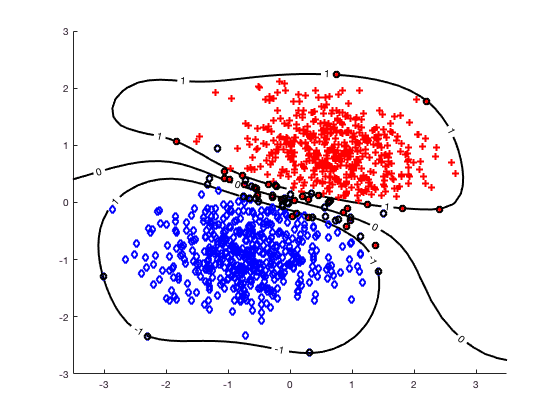

set(h3,'LineWidth',2)

axis([-3.5 3.5 -3 3])

## Report the figures you get from the exclass1.m and explain their meaning

% From this file it displays a distance matrix that has different columns of the number of support and number of number saturated on the given data.
% In the column titled Delta cost is the value in the row has a negative number it is listed as a bad mouve.
% The figure that appears is a 2D contour map that is shaded flat and used the Gaussian function as the kernel type and the results printed the outputs below:

 %C = 10
 %Kernel = Gaussian
 %Kernel option-1
 %Lambda -1.000e-07
 %n - 1000
 %nn- 41
 %sigma 0.3000
 %tps - 0.1300
 %w0 - 0.0192

